# Planteamiento de la cinemática inversa de la postura para un robot 4R

**Resumen**

Para resolver la cinemática inversa del robot 4R, se llevo a cabo la relación de lo siguiente:

- La posición $\left(x,y,z\right)$ del extremo (extraída de la cinemática directa).

- La orientación deseada del extremo (matriz de rotación o ángulos de Euler).

Estos se resolvieron en términos de las variables articulares $\theta_1$, $\theta_2$, $\theta_3$, $\theta_4$

**Definición de las funciones**

Matriz homogénea genérica:

syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Basándonos en la matriz homogénea, el procedimiento a realizado es el siguiente:

**1. Obtención del extremo deseado **$\left(x_{d,} ,y_d ,z_d \right)$

**2. Descomposición de las ecuaciones**:

- $\theta_1$, $\theta_2$ están asociados a $x$ e $y$.

- $\theta_3$ está asociado a $z$.

- $\theta_4$ depende de la orientación restante.

**3. Resolución iterativamente o analíticamente**: Usamos las relaciones trigonométricas para despejar los ángulos.

Las ecuaciones de posición para la cinemática inversa derivadas de las matrices de transformación son:

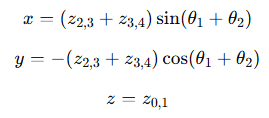

syms theta1 theta2 z_0_1 z_2_3 z_3_4 real

x = (z_2_3 + z_3_4) * sin(theta1 + theta2); % Posición en x
y = -(z_2_3 + z_3_4) * cos(theta1 + theta2); % Posición en y
z = z_0_1; % Posición en z

disp('Ecuaciones de posición para la cinemática inversa:');

Ecuaciones de posición para la cinemática inversa:


disp(['x = ', char(x)]);

x = sin(theta1 + theta2)*(z_2_3 + z_3_4)


disp(['y = ', char(y)]);

y = -cos(theta1 + theta2)*(z_2_3 + z_3_4)


disp(['z = ', char(z)]);

z = z_0_1


**Desarrollo**

Resolvemos z; de la ecuación z=z0,1�, de la cual es posible identificar directamente la relación entre la posición del extremo y el desplazamiento vertical inicial.

Definimos el parámetro z0_1 y la posición deseada z_d.

z0_1 = 0.15; % Altura inicial del robot (en metros)
z_d = 0.1; % Coordenada z (en metros)

if z_d <= z0_1
    disp('La posición z es alcanzable.');
else
    error('La posición z excede el rango del robot.');
end

La posición z es alcanzable.


Resolvemos θ1 + θ2; De las ecuaciones de posición en el plano XY

**tan(θ1 + θ2) = x / -y**

Calculamos θ1 + θ2 en función de la posición deseada (x_d, y_d).

x_d = 0.3; % Coordenada x deseada (en metros)
y_d = 0.2; % Coordenada y deseada (en metros)

Ángulo θ1 + θ2

phi = atan2(x_d, -y_d); % Relación de proyección en el plano XY
disp(['\theta_1 + \theta_2 (phi) = ', num2str(phi), ' rad']);

\theta_1 + \theta_2 (phi) = 2.1588 rad


Resolvemos θ1 y θ2 individualmente, para descomponer θ1 + θ2 en θ1 y θ2, utilizamos las longitudes de los eslabones. 

L1 = 0.5; % Longitud del primer eslabón (en metros)
L2 = 0.5; % Longitud del segundo eslabón (en metros)

Distancia en el plano XY

r = sqrt(x_d^2 + y_d^2);

Para encontrar θ2 se emplea la Ley de los cosenos

 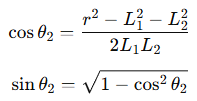   de la cual obtenemos; 

cos_theta2 = (r^2 - L1^2 - L2^2) / (2 * L1 * L2);
if abs(cos_theta2) > 1
    error('La posición deseada no es alcanzable: fuera del rango del robot.');
end
sin_theta2 = sqrt(1 - cos_theta2^2);
theta_2 = atan2(sin_theta2, cos_theta2);

Obtenemos θ1 utilizando proyecciones geométricas

theta_1 = atan2(y_d, x_d) - atan2(L2 * sin(theta_2), L1 + L2 * cos(theta_2));

disp(['\theta_1 = ', num2str(theta_1), ' rad']);

\theta_1 = -0.61393 rad


disp(['\theta_2 = ', num2str(theta_2), ' rad']);

\theta_2 = 2.4039 rad


disp(['\theta_1 + \theta_2 = ', num2str(phi), ' rad']);

\theta_1 + \theta_2 = 2.1588 rad


Resolvemos θ3, la posición vertical del robot

L3 = 0.2; % Longitud del eslabón asociado a \theta_3

theta_3 = acos((z_d - L3) / L3);

Por último θ4, recordando que este valor se ajusta según la orientación deseada del extremo.

En este caso asumimos que la orientación deseada es neutra para simplificar.

theta_4 = 0;

disp(['\theta_4 = ', num2str(theta_4), ' rad']);

\theta_4 = 0 rad


Resultados finales, mostramos los valores de todos los ángulos articulares.

disp('Ángulos articulares calculados (en radianes):');

Ángulos articulares calculados (en radianes):


disp(['\theta_1: ', num2str(theta_1)]);

\theta_1: -0.61393


disp(['\theta_2: ', num2str(theta_2)]);

\theta_2: 2.4039


disp(['\theta_3: ', num2str(theta_3)]);

\theta_3: 2.0944


disp(['\theta_4: ', num2str(theta_4)]);

\theta_4: 0


Por lo tanto las ecuaciones obtenidas son;